clear all
load("data\longitudinal_data")
load("data\mass_properties")


**Współczynniki masowe kalkulacje**

% I_yy_CG = I_YY_b

I_YY_b = Iyy + Mass* (l_cg^2)

I_YY_b = 5.2783e+07

**Wspolczynniki do macierzy I równania**

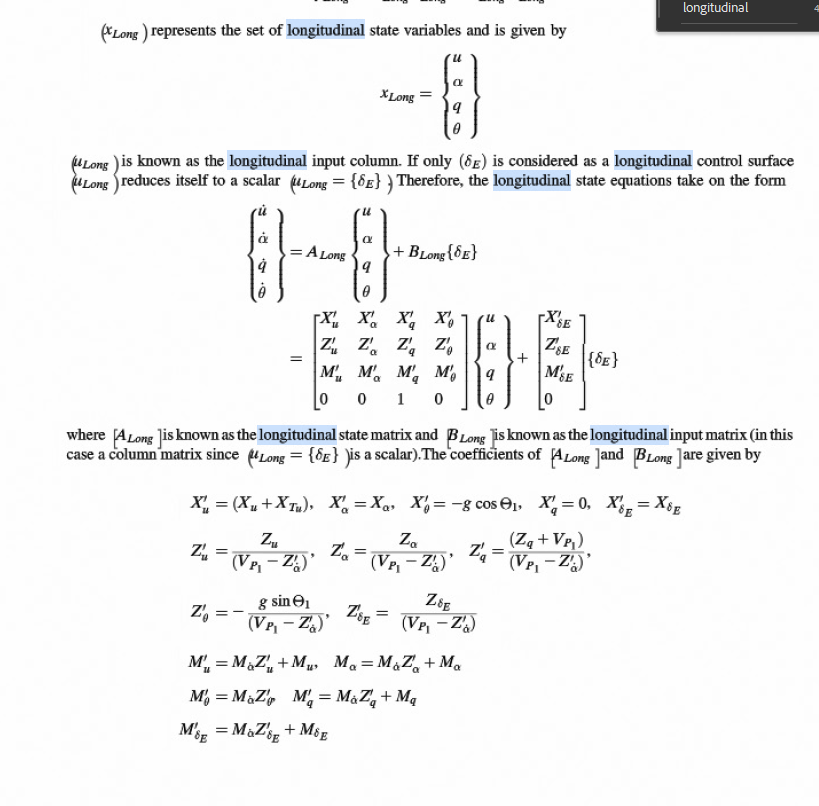

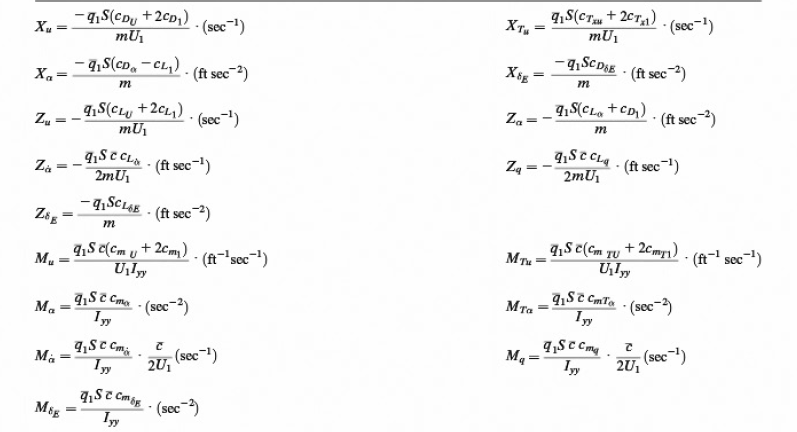

**%%%%%%%%%%%%%%%%%%%%    X   %%%%%%%%%%%%%%%%%%%%%%%%%**

**X'u**

X_u = (-dynamic_pressure(2, 4)*S*(C_Du+(2*C_D1(2, 4))))/ (Mass* Vp1(2, 4))

X_u = -0.0063

X_tu = (dynamic_pressure(2, 4)*S*(C_xTu(2, 4)+2*C_xT1(2, 4)))/(Mass*Vp1(2, 4))

X_tu = -0.0027

dX_u = X_u + X_tu

dX_u = -0.0090

**X'_alpha**

% dX_a = X_a
dX_a = (-dynamic_pressure(2, 4)*S*(C_Da(2, 4)-C_L1(2, 4)))/Mass

dX_a = 16.6938

**X'_theta**

theta_1 = alfa_1(2, 4)

theta_1 = 0.0581

dX_theta = -gravity_acceleration(1)*cos(theta_1)

dX_theta = -32.1157

**X'q**

dX_q = 0

dX_q = 0

**X'delta_e**

% dX_delta_e = X_delta_e
dX_delta_e = -(dynamic_pressure(2, 4)*S*C_Ddelta_E)/Mass

dX_delta_e = 0

**%%%%%%%%%%%%%%%%%%%%    Z   %%%%%%%%%%%%%%%%%%%%%%%%%**

**Z'alpha_dot**

Z_a_dot = (-dynamic_pressure(2, 4)*S*MAC*C_La_dot(4))/(2*Mass*Vp1(2, 4))

Z_a_dot = -2.4311

dZ_a_dot = Z_a_dot/Vp1(2, 4)

dZ_a_dot = -0.0039

**Z'alpha**

Z_a = (-dynamic_pressure(2, 4)*S*(C_La(4)+C_D1(2, 4)))/Mass

Z_a = -432.2953

dZ_a = Z_a/(Vp1(2, 4) - dZ_a_dot)

dZ_a = -0.6949

**Z'u**

Z_u = ((-dynamic_pressure(2, 4))*S*(C_Lu(2, 4)+2*C_L1(2, 4)))/(Mass*Vp1(2, 4))

Z_u = -0.1325

dZ_u = Z_u/(Vp1(2, 4) - dZ_a_dot)

dZ_u = -2.1305e-04

**Z'q**

Zq = -(dynamic_pressure(2, 4)*S*MAC*C_Lq(4))/(2*Mass*Vp1(2, 4))

Zq = -11.2176

dZ_q = (Zq + Vp1(2, 4))/(Vp1(2, 4) - dZ_a_dot)

dZ_q = 0.9820

**Z'theta**

dZ_theta = -(gravity_acceleration(2)*sin(theta_1))/(Vp1(2, 4) - dZ_a_dot)

dZ_theta = -0.0030

**Z'delta_e**

Z_delta_e = -(dynamic_pressure(2, 4)*S*c_Ldelta_E(4))/Mass

Z_delta_e = -25.7538

dZ_delta_e = Z_delta_e/(Vp1(2, 4)-dZ_a_dot)

dZ_delta_e = -0.0414

**%%%%%%%%%%%%%%%%%%%%    M   %%%%%%%%%%%%%%%%%%%%%%%%%**

**M'a**

M_a_dot = (dynamic_pressure(2, 4)*S*(MAC^2)*C_m_alpha_dot(4))/(2*I_YY_b*Vp1(2, 4))

M_a_dot = -0.0302

M_a = (dynamic_pressure(2 ,4)*S*MAC*C_ma(4))/I_YY_b

M_a = -0.2527

dMa = M_a_dot*dZ_a+M_a

dMa = -0.2317

**M'u**

Mu = (dynamic_pressure(2, 4)*S*MAC*(C_mu(2 ,4)+(2*C_m1)))/(I_YY_b*Vp1(2 ,4))

Mu = -8.7035e-06

dMu = M_a_dot*dZ_u+Mu

dMu = -2.2647e-06

**M'delta_E**

M_delta_E = (dynamic_pressure(2, 4)*S*MAC*C_mdelta_E(4))/I_YY_b

M_delta_E = -0.2721

dM_delta_E = M_a_dot*dZ_delta_e+M_delta_E

dM_delta_E = -0.2709

**M'q**

M_q = ((dynamic_pressure(2, 4)*S*MAC*C_mq(4))/Iyy)*(MAC/(2*Vp1(2, 4)))

M_q = -0.6030

dMq = M_a_dot * dZ_a + M_q

dMq = -0.5820

**M'theta**

dM_theta = M_a_dot*dZ_theta

dM_theta = 9.0796e-05

**Wspolczynniki do macierzy II równania**

**Z''_a**

ddZa = dZ_a*Vp1(2, 4)-gravity_acceleration(1)*sin(theta_1)

ddZa = -434.1616

**Z''_u**

ddZu = dZ_u*Vp1(2, 4)

ddZu = -0.1325

**Z''_q**

ddZq = (dZ_q-1)*Vp1(2, 4)

ddZq = -11.2214

**Z''_theta**

ddZ_theta = dZ_theta*Vp1(2, 4) + gravity_acceleration(1)*sin(theta_1)

ddZ_theta = 1.1740e-05

**Z''_delta_E**

ddZ_delta_E = dZ_delta_e*Vp1(2, 4)

ddZ_delta_E = -25.7536

**%%%%%%%%%%%%%%%%%%%%    MACIERZE   %%%%%%%%%%%%%%%%%%%%%%%%%**

**A**

A = [dX_u dX_a dX_q dX_theta;
    dZ_u dZ_a dZ_q dZ_theta;
    dMu dMa dMq dM_theta;
    0 0 1 0]

A =    -0.0090   16.6938         0  -32.1157
   -0.0002   -0.6949    0.9820   -0.0030
   -0.0000   -0.2317   -0.5820    0.0001
         0         0    1.0000         0


**B**

B = [dX_delta_e;
    dZ_delta_e;
    dM_delta_E;
    0]

B =          0
   -0.0414
   -0.2709
         0


**C**

C = [ddZa ddZu ddZq ddZ_theta;
    1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1]

C =  -434.1616   -0.1325  -11.2214    0.0000
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


**D**

D = [ddZ_delta_E;
    0;
    0;
    0;
    0]

D =   -25.7536
         0
         0
         0
         0
